# Measure Nab Granules in a single time point

This script is described in: Jeremy C. Hunn, Katherine M. Hutchinson, Joshua B. Kelley, Daniel Reines  AN ALGORITHM TO QUANTIFY INDUCIBLE PROTEIN CONDENSATES IN EUKARYOTIC CELLS. bioRxiv DOI:...

This script takes two input images, one of which will be used to make individual masks for each cell (here the nucleus based on histone signal specifically, but whole cell masks could be used) and the other of which is the protein of interest (Nab) that will be assessed for granule formation. The default values below work for our Nab3 and histone images, but may need to be adjusted for other systems or conditions.

The script will record the granules detected over a range of size cutoffs for granules and save that data as an excel file to help assess the appropriate parameters for scoring a granule.  

## Load images

% Variables that may require adjustment to adapt to individual data sets


nucthresh = 17;  % pick a nuclear mask intensity threshold
nucmaskmin = 40; % lower limit of contiguous pixels to be considered a nucleus;
numstddev = 3;   % minimum number of standard deviations above the mean a pixel needs to
% be to be considered part of a granule
ExcludeBrightPixels = 1; % set to 1 to exlude the brightest pixels from the mean calculation, set to 0 to skip this step
numbrightpixels = 10; % number of brightest pixels to omit from calculation of nuclear mask mean greater than
% or equal to 1
k=20; % upper limit of granule size

[nabname, nabpath] = uigetfile({'*.png';'*.tif'},'Select Nab Image');
[histname, histpath] = uigetfile({'*.png';'*.tif'},'Select Histone Image');
fileoutput = uiputfile('*.xlsx','Choose Filename For Spreadsheet Output');
savespace = uiputfile('*.mat','Choose Filename For MATLAB Workspace');

histones = [];
nab = [];

histones = imread(fullfile(histpath, histname));
nab = imread(fullfile(nabpath, nabname));


## Generate nuclear mask from histones

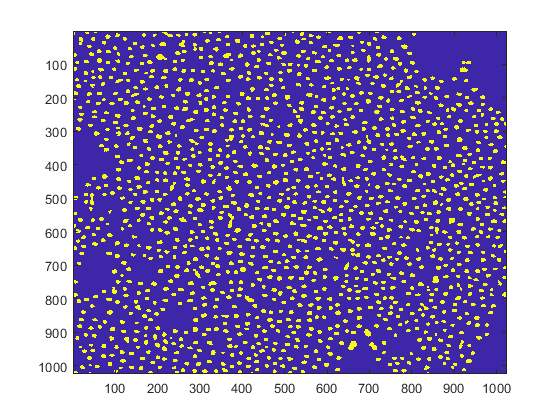



nuc = histones > nucthresh;
nuc = bwmorph(nuc, 'open'); % this cleans up the edges of the masks
nuc = bwareaopen(nuc, nucmaskmin); % this removes objects smaller than 40, real nuclei seem to be at least 50

figure()
imagesc(nuc)

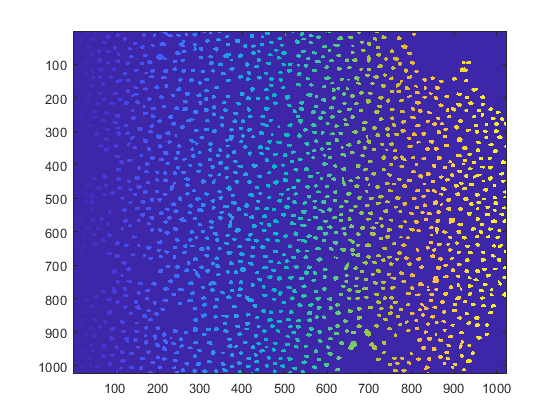


nuccm = labelmatrix(bwconncomp(nuc));

numnuc = max(max(nuccm)); %how many nuclei in the nuclear label mask?

figure()
imagesc(nuccm)

## Get Nab info for each nucleus

nabdata = [];
granarray=[];
nabdataoutput = [];

granulemask = zeros(size(nab));


for i = 1:max(max(nuccm));
    nabdata(i).identify = i;
    nabdata(i).nuc = nab(nuccm==i);
    nabdata(i).mean = mean(nabdata(i).nuc);
    nabdata(i).median = median(nabdata(i).nuc);
    nabdata(i).std = std(double(nabdata(i).nuc));
    
    if ExcludeBrightPixels ==1;
        nabdata(i).sorted = sort(nabdata(i).nuc, 'descend');
        %     if size(nabdata(i).sorted, 1) > 11;
        nabdata(i).top = nabdata(i).sorted(1:numbrightpixels);         % number of brightest pixels to omit from calculation of mean
        nabdata(i).bottom = nabdata(i).sorted(numbrightpixels+1:end);
        nabdata(i).bmean = mean(nabdata(i).bottom);
        nabdata(i).bstd = std(double(nabdata(i).bottom));
        nabdata(i).granthresh = nabdata(i).bmean + numstddev*nabdata(i).bstd;
    else
        nabdata(i).granthresh = nabdata(i).mean + numstddev*nabdata(i).std;
        nabdata(i).bmean = nabdata(i).mean;
    end
    
    
    nabdata(i).spot = bwconncomp((nuccm == i & nab > nabdata(i).granthresh));
    nabdata(i).spotnum = nabdata(i).spot.NumObjects;
    
    
end

nabnuctotal = [];
for i = 1:numnuc;
    nabnuctotal(i)= nabdata(i).bmean;
end

nabnuctmean = mean(nabnuctotal);
nabnuctstd = std(nabnuctotal);

for j=1:k
    
    granarray(j).num = j-1;
    granarray(j).grancells=0;

grannum = 0; % store number of granule containing cells
cellmnum = 0; % store number of cells measured
cellexcluded = 0;

nabproportion = []; % column 1 is total nab intensity, column 2 is nab intensity in granule

for i = 1:1:max(max(nuccm));
    nabdata(i).spotsizes = 0;
    if nabdata(i).mean > nabnuctmean - nabnuctstd;
        cellmnum = cellmnum +1;
        if nabdata(i).spotnum >= 0; 
            for ob = 1:nabdata(i).spotnum; % go through each spot and
                nabdata(i).spotsizes(ob) = size(nabdata(i).spot.PixelIdxList{1,ob},1); % find out how many pixels are in it
                if nabdata(i).spotsizes(ob)==j-1
                granarray(j).grancells = granarray(j).grancells + 1;
                end
            end
            
            
         
            %determine if its a granule
           
            if any(nabdata(i).spotsizes >= j-1);
                nabdata(i).granule = 1;
                granulemask((nuccm == i & nab > nabdata(i).granthresh)) = i;
                grannum = grannum + 1;
                %if any(nabdata(i).spotsizes==j-1)
                %granarray(j).grancells = granarray(j).grancells + 1;
                %end
                if any(nabdata(i).spotsizes == 0);
                    granarray(1).grancells = granarray(1).grancells + 1;
                end
                nabproportion(i,1) = sum(sum(nab(nuccm==i)));
                nabproportion(i,2) = sum(sum(nab(nuccm == i & (nab > nabdata(i).granthresh) )));
            else
                nabdata(i).granule = 0;
            end
        end
    else
        cellexcluded = cellexcluded + 1;
        nabdata(i).spotsizes = 0;
        nabdata(i).granule = 0;
    end
    


end
granarray(j).fracgran = 100*(grannum/cellmnum);

end

## Summary

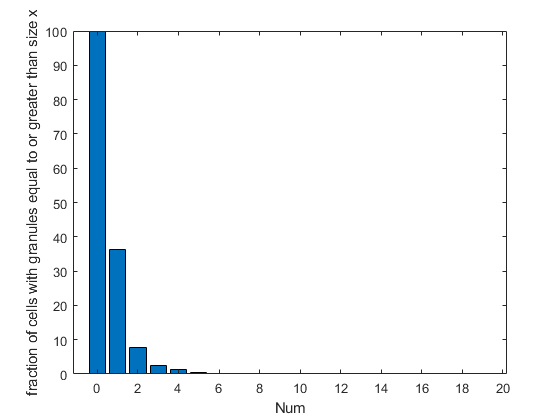


x = [granarray(1:k).num];
y = [granarray(1:k).fracgran];

figure(1)
bar(x,y)
xlabel('Num')
ylabel('fraction of cells with granules equal to or greater than size x')

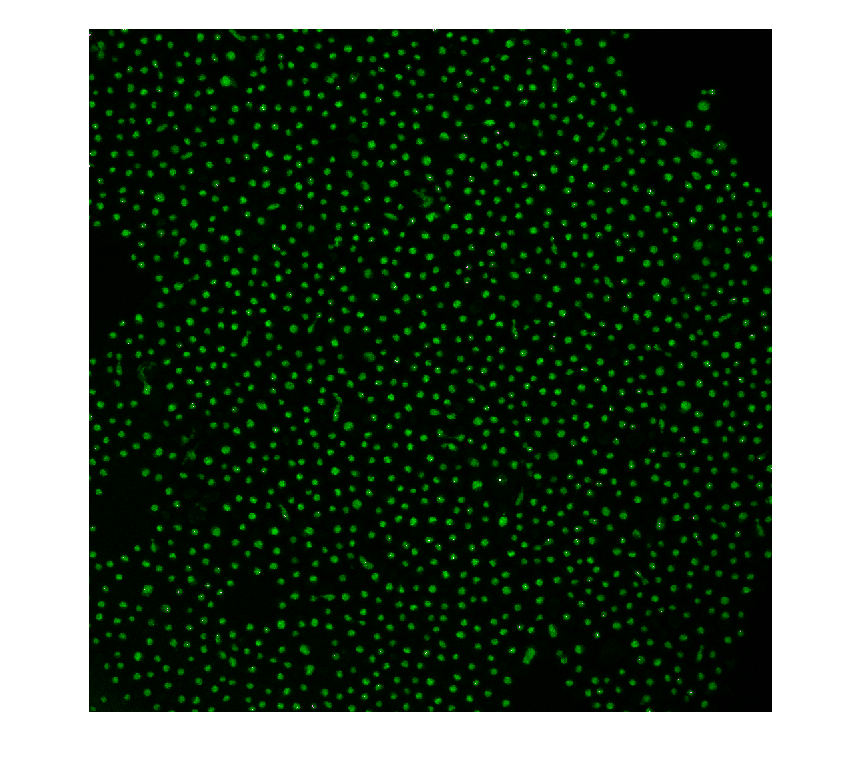


granarray(1).nab_name = nabname;
granarray(1).histone_name = histname;
granarray(1).num_nuc = numnuc;
granarray(1).cell_mnum = cellmnum;
granarray(1).cell_excl = cellexcluded;

figure();
imshowpair(nab, 255*uint8(granulemask > 0))


T = struct2table(granarray);
writetable(T, fileoutput,'Sheet',1);
save(savespace)